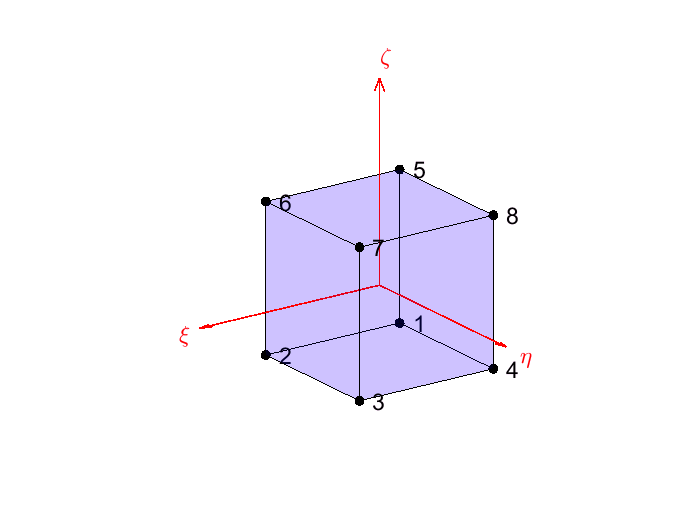

[xi,eta,zeta]=meshgrid([-1,1],[-1,1],[-1,1]);
reordering=[1,3,4,2,5,7,8,6]';
xi=xi(reordering);eta=eta(reordering);zeta=zeta(reordering); % coordinates of the reference element
x=xi;% nodal coordinates
y=1/2*eta.*(xi+2); 
z=1/2*zeta.*(xi+2);
figure
scatter3(xi,eta,zeta,'filled','k')
hold on
grid on
axis equal
axis off
%axis([-3,3,-3,3,-3,3])
for k=1:8
text(xi(k),eta(k),zeta(k),['  ',num2str(k)],'FontSize',14,'Color','k');
end
FACES=[1 2 3 4;5 6 7 8;2 3 7 6;3 4 8 7;4 1 5 8;1 2 6 5];
patch('Faces',FACES,'Vertices',[xi,eta,zeta],'FaceColor','b','FaceAlpha',0.1)
quiver3(0,0,0,3,0,0,'LineWidth',1,'Color','r')
text(3,0,0,'\xi','FontSize',14,'Color','r')
quiver3(0,0,0,0,3,0,'LineWidth',1,'Color','r')
text(0,3,0,'\eta','FontSize',14,'Color','r')
quiver3(0,0,0,0,0,3,'LineWidth',1,'Color','r')
text(0,0,3,'\zeta','FontSize',14,'Color','r')
view(145,20)
print('reference_element','-dpng')

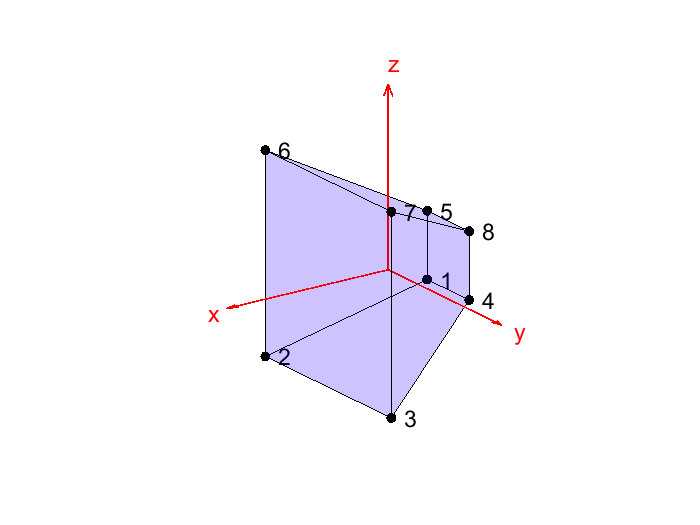

figure
scatter3(x,y,z,'filled','k')
hold on
grid on
axis equal
axis off
%axis([-3,3,-3,3,-3,3])
for k=1:8
text(x(k),y(k),z(k),['  ',num2str(k)],'FontSize',14,'Color','k');
end
FACES=[1 2 3 4;5 6 7 8;2 3 7 6;3 4 8 7;4 1 5 8;1 2 6 5];
patch('Faces',FACES,'Vertices',[x,y,z],'FaceColor','b','FaceAlpha',0.1)
quiver3(0,0,0,3,0,0,'LineWidth',1,'Color','r')
text(3,0,0,'x','FontSize',14,'Color','r')
quiver3(0,0,0,0,3,0,'LineWidth',1,'Color','r')
text(0,3,0,'y','FontSize',14,'Color','r')
quiver3(0,0,0,0,0,3,'LineWidth',1,'Color','r')
text(0,0,3,'z','FontSize',14,'Color','r')
view(145,20)
print('mapped_element','-dpng')